# Social proximity analysis

## Load data

clear all
% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

% Specify the index of session to be loaded
%% 240207
% recID = 3;
% recID = 4;
% recID = 5;
%% 240208
% recID = 6;
% recID = 7;
% recID = 8;
%% 240209_1
% recID = 9;
% recID = 10;
%% 240209_2
% recID = 11;
%% 240210_1
recID = 12;
% recID = 13;
%% 240210_2
% recID = 14;
%% 240211_1
% recID = 15;
% recID = 16;
% recID = 17;
%% 240211_2
% recID = 18;
%% 240212
% recID = 19;
% recID = 20;
% recID = 21;


% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

cd(rootdir)

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
% dataTypes = 'barslm'; % data types to be loaded
% [BhvData,AnalogData,RewardData,spikeData,lfpData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data
dataTypes = 'barsm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240210_1 ...
Loading analog signals ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading behavioral data ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading reward data ...
Final MinPeakDistance was 1.0 
224 peaks were detected. 
2 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Loading spike data ...
Kilosort outputs found
Manual curation found
Loading meta data ...


% dataTypes = 'barm'; % data types to be loaded
% [BhvData,AnalogData,RewardData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data
% dataTypes = 's'; % data types to be loaded
% [spikeData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data
Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
[Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData,'include','all');

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
unit_ids = spikeData.good_units.cluster_id;
regions = cell(length(unit_ids),1);
for unit = 1:length(unit_ids)
    unit_id = unit_ids(unit);
    depth = spikeData.good_units.depth(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    regions{unit} = region;
end
spikeData.good_units.region = regions;

## Behavioral analysis

### Build adjacency matrix

An adjacency is defined as a scaled distance between two individual bats. The element of an adjacency matrix $A_{t\;}$ is 


$$A_{i,j,t} =\exp \left(\frac{-||x_{i,t} -x_{j,t} ||_2^2 }{\sigma \;}\right)$$


where i and j indicate bats. The $\sigma \;$is the scaling coeeficient determined so that the adjacency $A_{i,j,t}$ equals 0.5 when the euclidean distance between bats equal to the threshold (=0.3 m).

To compute an adjacency matrix, the adjacency between each pair of bats are calculated for the extracted frames during a session. Only the data points at which both of the pairwise bats are resting at perches are considered.

(Sanity check) I need to double check that the bats are at resting sites in the most times and the extraction above does not affect the results.

-> The # of data points when all the bats were resting was half of the ones that any of the bats were resting. So consider any data points that the target pairwise bats are resting.

% Load behavioral and neural features
blanding = 1-BhvData.bflying;
t = BhvData.t;
r = BhvData.r;
T = BhvData.T;
n_bats = BhvData.n_tags;
r_lim = BhvData.r_lim;
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');

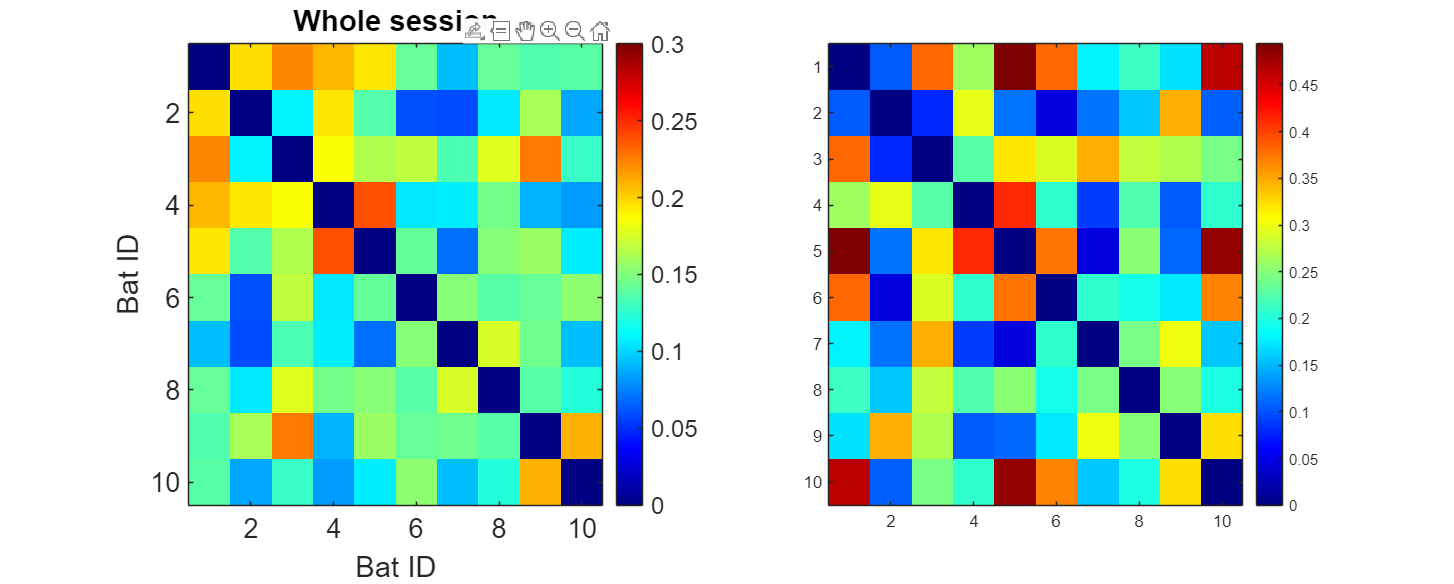

% Threshold for adjacency evaluation
th_adj = 0.5;
coeff_adj = th_adj^2/(log(2)); % scaling coefficient

% Identify when all bats are resting
% blanding_all = all(blanding,2);

% Create adjacency matrix
adj_mat = zeros(n_bats,n_bats);
adj_w_mat = zeros(n_bats,n_bats);
adj_trace = cell(n_bats,n_bats);
adj_w_trace = cell(n_bats,n_bats);
t_adj_trace = cell(n_bats,n_bats);
len_adj_trace = cell(n_bats,n_bats);

% Specify a pair of bat
for bb = 1:n_bats
    for bbb = 1:n_bats
        if bb ~= bbb
            blanding_all = blanding(:,bb) .* blanding(:,bbb); % 1 when both pairwise bats are resting
            
            % Identify the time when new states happen
            t_start_idx = find(diff([blanding_all(1); blanding_all])==1); % timestamp when the network changes
            t_end_idx = find(diff([blanding_all(1); blanding_all])==-1); % timestamp when the network changes
            if blanding_all(1) == 0 && blanding_all(end) == 0
            elseif blanding_all(1) == 0 && blanding_all(end) == 1
                t_start_idx = t_start_idx(1:end-1);
            elseif blanding_all(1) == 1 && blanding_all(end) == 0
                t_end_idx = t_end_idx(2:end);
            elseif blanding_all(1) == 1 && blanding_all(end) == 1
                t_start_idx = t_start_idx(1:end-1);
                t_end_idx = t_end_idx(2:end);
            end

            t_start_sec = t(t_start_idx); % time when the network changes
            t_end_sec = t(t_end_idx);
            
            t_len_sec = t_end_sec-t_start_sec; % length of each state
            t_sum_sec = sum(t_len_sec); % total time fractions

            % Compute adjacency
            adj = exp(-1*vecnorm(r(t_start_idx,:,bb)-r(t_start_idx,:,bbb),2,2).^2/(coeff_adj));

            % Update the adjacency matrix
            adj_mat(bb,bbb) = mean(adj);
            adj_w_mat(bb,bbb) = sum(adj.*t_len_sec/t_sum_sec);
            adj_trace{bb,bbb} = adj;
            adj_w_trace{bb,bbb} = adj.*t_len_sec/t_sum_sec;
            t_adj_trace{bb,bbb} = t_start_sec;
            len_adj_trace{bb,bbb} = t_len_sec;
        end
    end
end

% FIGURE
figure
set(gcf,'units','normalized','Position',[0.1 0.1 0.7 0.5])
subplot(1,2,1)
imagesc(adj_mat)
colorbar
colormap jet
clim([0 0.3])
title('Whole session')
xlabel('Bat ID')
ylabel('Bat ID')
set(gca, 'FontSize',16)

subplot(1,2,2)
imagesc(adj_w_mat)
colorbar
colormap jet

The resultant matrix could not be clustered well. It might be because of low values in the matrix.

% Visualize the adjacency matrix
% A = adj_mat;
% A_clu = clusterdata(A,'criterion','distance','distance','euclidean','cutoff',0.2);
% A_clu = reorder_index(A_clu,'descend');
% [~,b_idx] = sort(A_clu);
% A_sort = sort_array(A,b_idx);
% 
% figure; imagesc(A_sort)
% title('Sorted')
% xticklabels(b_idx); yticklabels(b_idx);
% xlabel('Bat ID'); ylabel('Bat ID')
% set(gca,'FontSize',16)
% colorbar; colormap jet

#### Shuffling test

To test if the detected adjacency is true, do a shuffling test

% Shuffling test
n_ites = 300;

% Adjacency matrix for shuffled data
adj_mat_shuffle = zeros(n_bats,n_bats,n_ites);
for n = 1:n_ites
    [adj_trace,~,~] = compute_adjacency(BhvData,'shuffle',true);
    adj_mat = cellfun(@mean, adj_trace);
    adj_mat(isnan(adj_mat)) = 0;
    adj_mat_shuffle(:,:,n) = adj_mat;
end

% True adjancency matrix
[adj_trace,~,~] = compute_adjacency(BhvData);
adj_mat = cellfun(@mean, adj_trace);
adj_mat(isnan(adj_mat)) = 0;
adj_mat_true = adj_mat;

p_adj = sum(adj_mat_shuffle > adj_mat_true,3)/n_ites;
adj_index = adj_mat_true - mean(adj_mat_shuffle,3);

%%% FIGURE
fig = figure;
set(gcf,'units','normalized','Position',[0 0.1 1 0.5])

ax = subplot(1,3,1);
imagesc(adj_mat_true)
set(gca,'FontSize',16)
colorbar
colormap(ax,'jet')
clim([0 0.3])
title('Adjacency matrix')
xlabel('Bat')
ylabel('Bat')

ax = subplot(1,3,2);
imagesc((1-eye(n_bats,n_bats)).*(p_adj > 0.999 | p_adj < 0.001))
set(gca,'FontSize',16)
C = redblue(256);
colormap(ax,C)
clim([-1 1])
title('shuffle test (p<0.001)')
xlabel('Bat')
ylabel('Bat')

ax = subplot(1,3,3);
C = redblue(256);
h = imagesc(adj_index/max(adj_index,[],'all'));
set(gca,'FontSize',16)
set(h, 'AlphaData', ~eye(n_bats,n_bats))
colorbar
colormap(ax,C)
clim([-1 1])
title('Adjacency index')
xlabel('Bat')
ylabel('Bat')

### Test different metrics

Instead of an adjancy, try to use other metrics such as time fractions and Euclidean distances to evaluate the proximity between two bats.

% Load behavioral and neural features
blanding = 1-BhvData.bflying;
t = BhvData.t;
r = BhvData.r;
T = BhvData.T;
n_bats = BhvData.n_tags;
r_lim = BhvData.r_lim;
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');

#### Eucledean distance

% Threshold for adjacency evaluation
th_adj = 0.5;
coeff_adj = th_adj^2/(log(2)); % scaling coefficient

% Identify when all bats are resting
% blanding_all = all(blanding,2);

% Create adjacency matrix
adj_mat_e = zeros(n_bats,n_bats);
adj_w_mat_e = zeros(n_bats,n_bats);
adj_trace_e = cell(n_bats,n_bats);
adj_w_trace_e = cell(n_bats,n_bats);
t_adj_trace_e = cell(n_bats,n_bats);

% Specify a pair of bat
for bb = 1:n_bats
    for bbb = 1:n_bats
        if bb ~= bbb
            blanding_all = blanding(:,bb) .* blanding(:,bbb); % 1 when both pairwise bats are resting
            
            % Identify the time when new states happen
            t_start_idx = find(diff([blanding_all(1); blanding_all])==1); % timestamp when the network changes
            t_end_idx = find(diff([blanding_all(1); blanding_all])==-1); % timestamp when the network changes
            t_start_sec = t(t_start_idx); % time when the network changes
            t_end_sec = t(t_end_idx);
            
            t_len_sec = t_start_sec-t_end_sec; % length of each state
            t_sum_sec = sum(t_len_sec); % total time fractions

            % Compute adjacency
            adj = vecnorm(r(t_start_idx,:,bb)-r(t_start_idx,:,bbb),2,2);

            % Update the adjacency matrix
            adj_mat_e(bb,bbb) = mean(adj);
            adj_w_mat_e(bb,bbb) = mean(adj.*t_len_sec/t_sum_sec);
            adj_trace_e{bb,bbb} = adj;
            adj_w_trace_e{bb,bbb} = adj.*t_len_sec/t_sum_sec;
            t_adj_trace_e{bb,bbb} = t_len_sec;
        end
    end
end

% FIGURE
figure
set(gcf,'units','normalized','Position',[0.1 0.1 0.7 0.5])
subplot(1,2,1)
imagesc(adj_mat_e)
colorbar
colormap jet

subplot(1,2,2)
imagesc(adj_w_mat_e)
colorbar
colormap jet

#### Time fraction at being together

th = 0.5 m

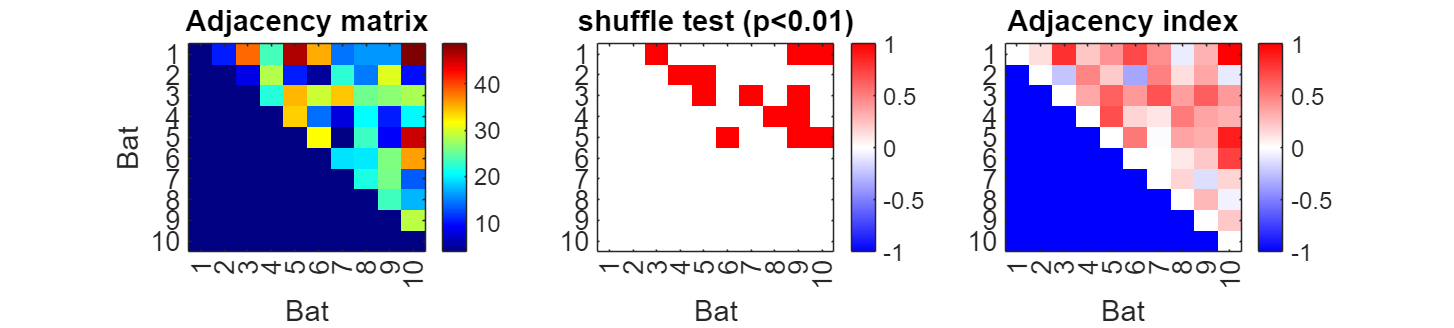

% Shuffling test
n_ites = 300;

% Attention!.... The result of the compute_adjacency function does not
% match with the one by compute_social_proximity function. There was no
% significant connections between bats when using the former function.
% Need to check if there is no bug

% % Adjacency matrix for shuffled data
% adj_mat_shuffle = zeros(n_bats,n_bats,n_ites);
% for n = 1:n_ites
%     adj_mat = compute_adjacency(BhvData,'shuffle',true,'type','time');
%     adj_mat(isnan(adj_mat)) = 0;
%     adj_mat_shuffle(:,:,n) = adj_mat;
% end
% 
% % True adjancency matrix
% adj_mat = compute_adjacency(BhvData,'type','time');
% adj_mat(isnan(adj_mat)) = 0;
% adj_mat_true = adj_mat;
% 
% % Compute p-value and adjacency index
% p_adj = sum(adj_mat_shuffle > adj_mat_true,3)/n_ites;
% adj_index = adj_mat_true - mean(adj_mat_shuffle,3);

[prx_mat, p_prx, prx_index] = compute_social_proximity(BhvData,n_ites);

%%% FIGURE
fig = figure;
set(gcf,'units','normalized','Position',[0 0.1 1 0.4])

ax = subplot(1,3,1);
imagesc(prx_mat(:,:,1))
set(gca,'FontSize',16)
colormap(ax,'jet')
colorbar
title('Adjacency matrix')
xlabel('Bat')
ylabel('Bat')
% grid(ax,'minor')
xticks(1:n_bats)
yticks(1:n_bats)

ax = subplot(1,3,2);
h = imagesc((1-eye(n_bats,n_bats)).*(p_prx > 0.99 | p_prx < 0.01));
set(gca,'FontSize',16)
set(h, 'AlphaData', ~isnan(prx_mat(:,:,1)))
% colorbar
C = redblue(256);
colormap(ax,C)
colorbar
clim([-1 1])
title('shuffle test (p<0.01)')
xlabel('Bat')
% ylabel('Bat')
% grid(ax,'minor')
xticks(1:n_bats)
yticks(1:n_bats)

ax = subplot(1,3,3);
C = redblue(256);
h = imagesc(prx_index/max(prx_index,[],'all'));
set(gca,'FontSize',16)
set(h, 'AlphaData', ~eye(n_bats,n_bats))
colorbar
colormap(ax,C)
clim([-1 1])
title('Adjacency index')
xlabel('Bat')
% grid(ax,'on')
xticks(1:n_bats)
yticks(1:n_bats)

% ylabel('Bat')

### Change of adjancency over time

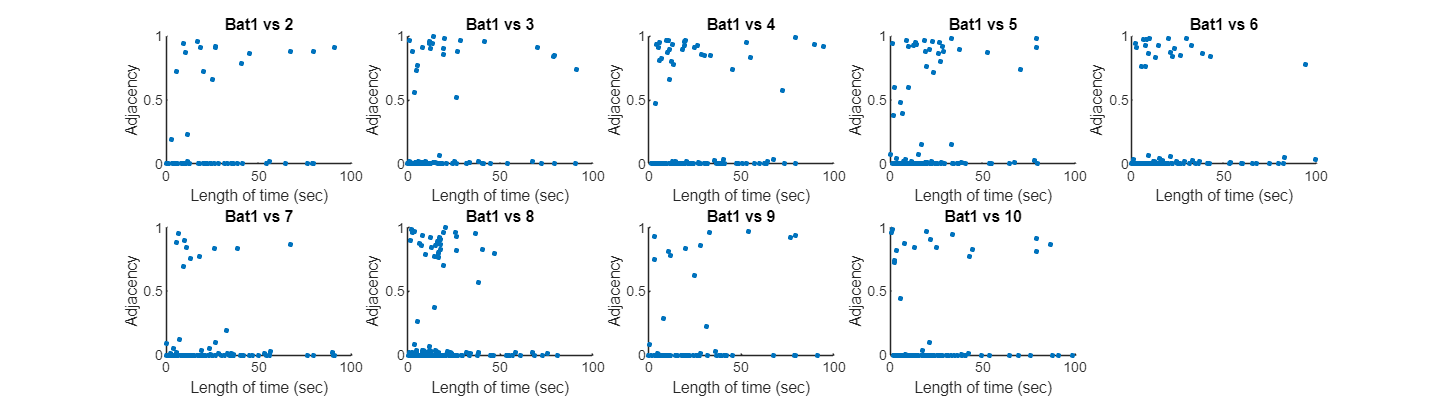

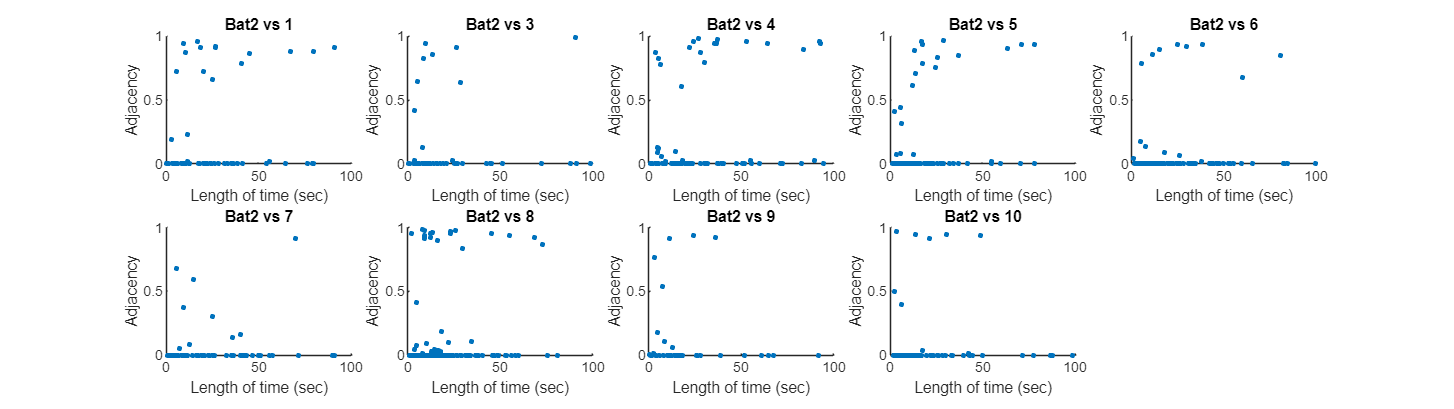

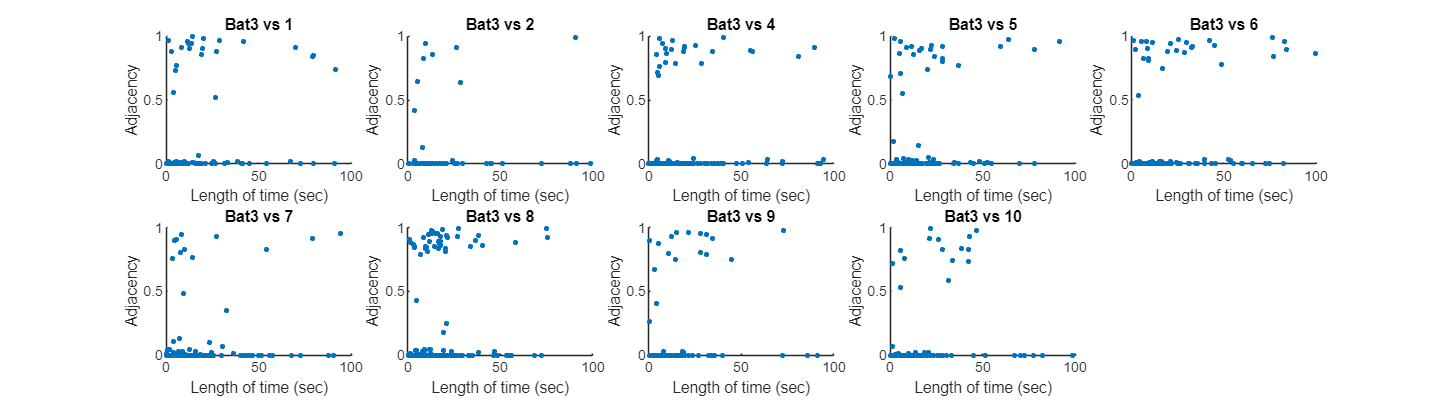

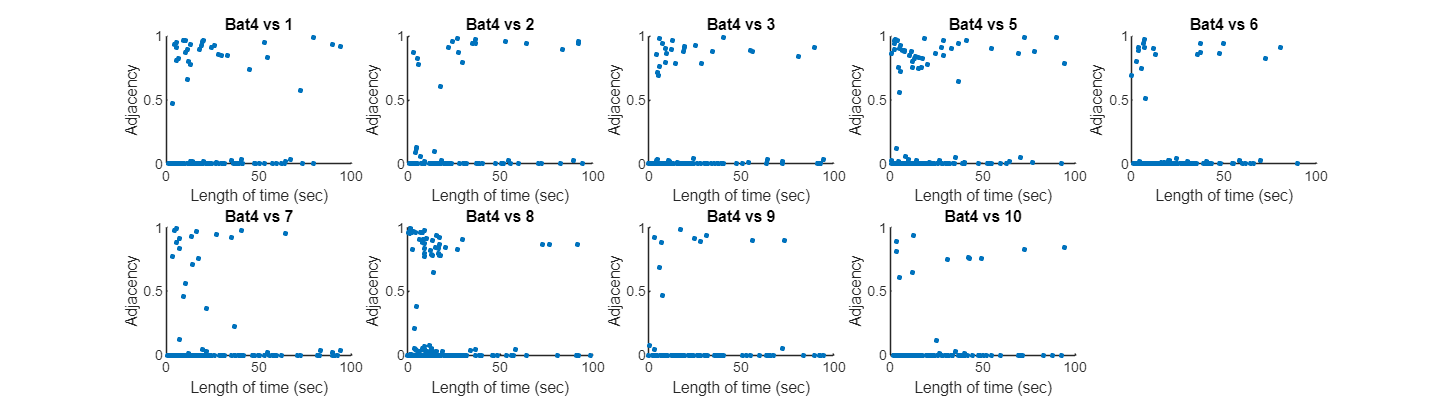

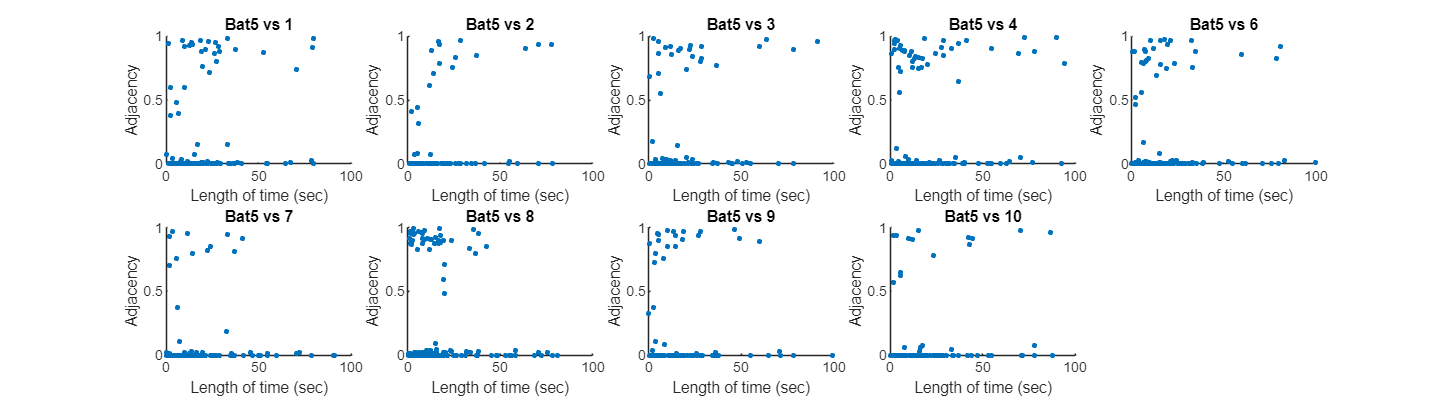

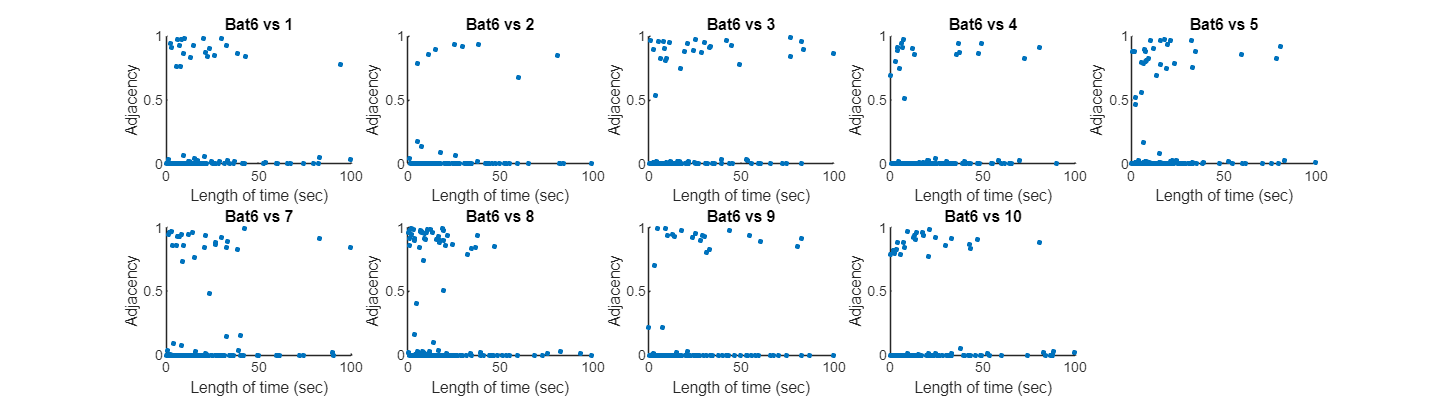

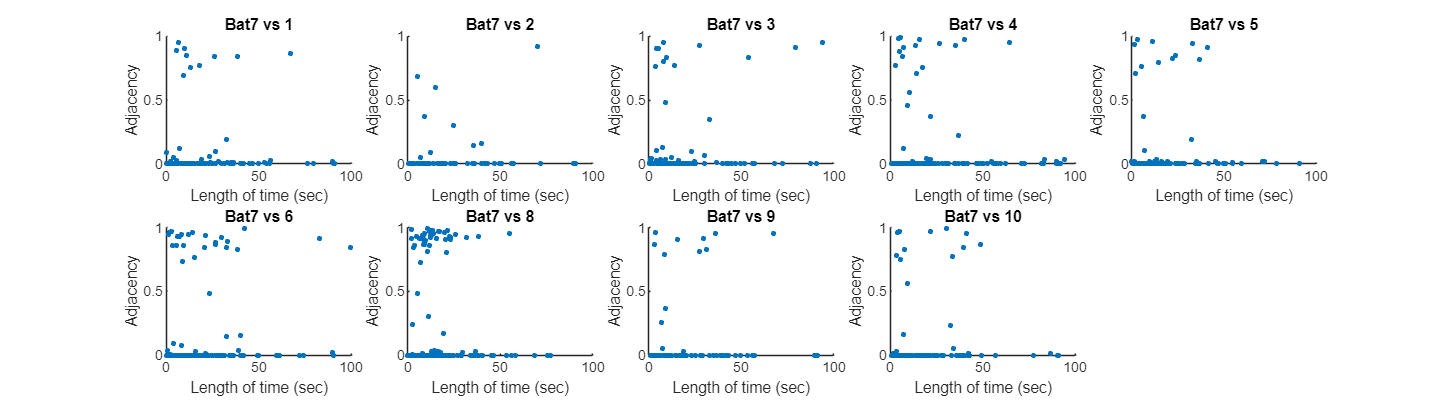

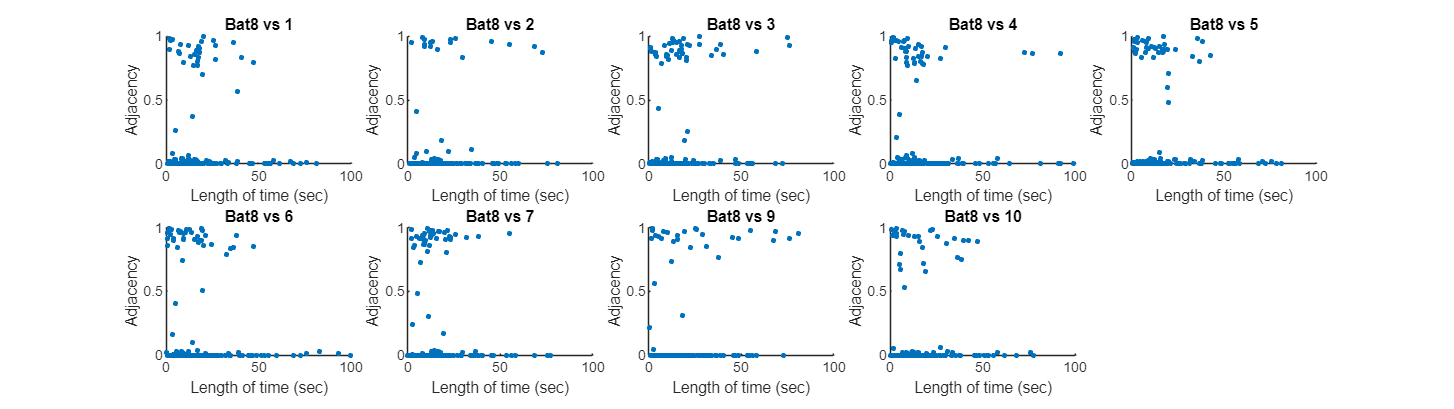

% adjacency vs length of being together
[adj_trace,t_adj_trace,len_adj_trace] = compute_adjacency(BhvData);
adj_mat = cellfun(@mean, adj_trace);
adj_mat(isnan(adj_mat)) = 0;
adj_mat_true = adj_mat;

for bb = 1:n_bats
    figure
    set(gcf,'Units','normalized','Position',[0 0.2 1 0.5])
    tiledlayout(2,5,'TileSpacing','tight')

    for bbb = 1:n_bats
        if bb < bbb
            adj = adj_trace{bb,bbb};
            t_adj = len_adj_trace{bb,bbb};
        elseif bb > bbb
            adj = adj_trace{bbb,bb};
            t_adj = len_adj_trace{bbb,bb};
        end

        str_title = sprintf('Bat%d vs %d',bb,bbb);

        if bb~=bbb
            nexttile
            scatter(t_adj,adj,10,'filled','o')
            xlabel('Length of time (sec)')
            ylabel('Adjacency')
            xlim([0,100])
            title(str_title)
        end
    end
end

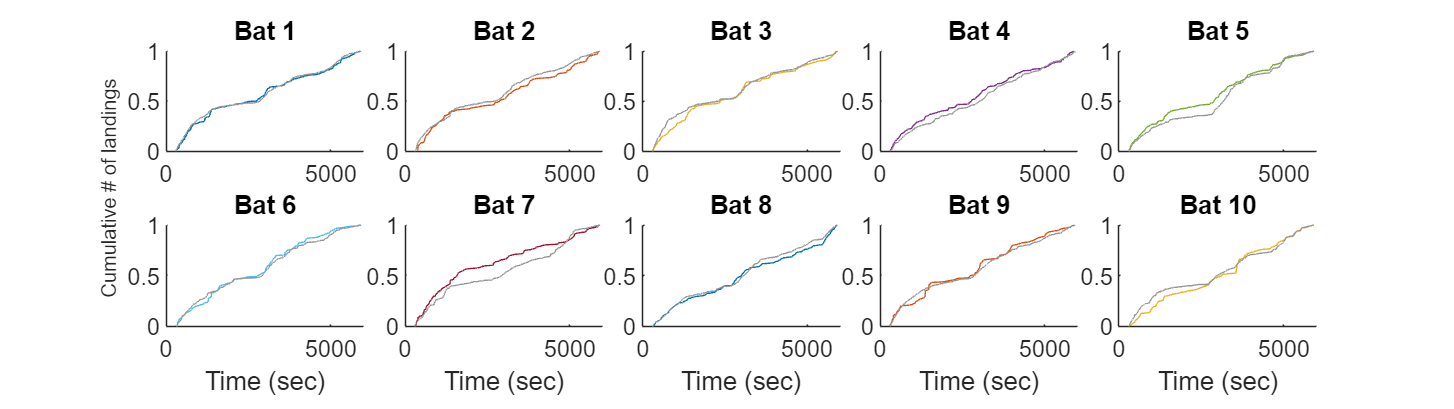

% Time course of adjacency
[adj_trace,t_adj_trace,len_adj_trace] = compute_adjacency(BhvData);
adj_mat = cellfun(@mean, adj_trace);
adj_mat(isnan(adj_mat)) = 0;
adj_mat_true = adj_mat;


figure
set(gcf,'Units','normalized','Position',[0 0.2 1 0.5])
tl = tiledlayout(2,5,'TileSpacing','tight');
ylabel(tl,'Cumulative # of landings')

for bb = 1:n_bats
    adj_all = [];
    t_all = [];
   
    for bbb = 1:n_bats
        if bb < bbb
            adj = adj_trace{bb,bbb};
            t_adj = t_adj_trace{bb,bbb};
        elseif bb > bbb
            adj = adj_trace{bbb,bb};
            t_adj = t_adj_trace{bbb,bb};
        end

        adj_all = [adj_all; adj];
        t_all = [t_all; t_adj];

        % str_title = sprintf('Bat%d vs %d',bb,bbb);
    end

    
    nexttile
    hold on
    [f_adj, x_adj] = ecdf(t_all(adj_all>0.5 & t_all > 300));
    plot(x_adj,f_adj,'Color',bat_clr(bb,:))
    [f_not, x_not] = ecdf(t_all(adj_all<=0.5 & t_all > 300));
    plot(x_not,f_not,'Color',[150 150 150]/255)
    % scatter(t_all,adj,10,bat_clr(bb,:),'filled','o')
    if bb > 5
        xlabel('Time (sec)')
    end
    xlim([0,t(end)])
    title(sprintf('Bat %d',bb))
    set(gca,'FontSize',14)
end

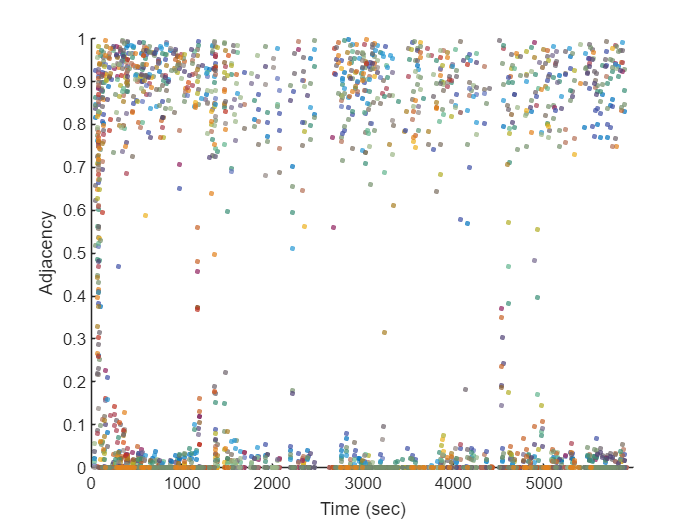

% Time course of adjacency for all bats
% Time course of adjacency
bat_clr = BhvData.bat_clr;

[adj_trace,t_adj_trace,len_adj_trace] = compute_adjacency(BhvData);
adj_mat = cellfun(@mean, adj_trace);
adj_mat(isnan(adj_mat)) = 0;

adj_all = [];
t_all = [];
c_vector = [];
for bb = 1:n_bats
    for bbb = 1:n_bats
        if bb < bbb
            adj_all = [adj_all;adj_trace{bb,bbb}];
            t_all = [t_all;t_adj_trace{bb,bbb}];
            new_clr = mean(bat_clr([bb,bbb],:),1);
            c_vector = [c_vector; repmat(new_clr,length(adj_trace{bb,bbb}),1)];
        end
    end
end

figure;
scatter(t_all,adj_all,10,c_vector,'filled','o','MarkerFaceAlpha',0.7)
xlabel('Time (sec)')
ylabel('Adjacency')
xlim([0,t(end)])

### Stability of adjacency

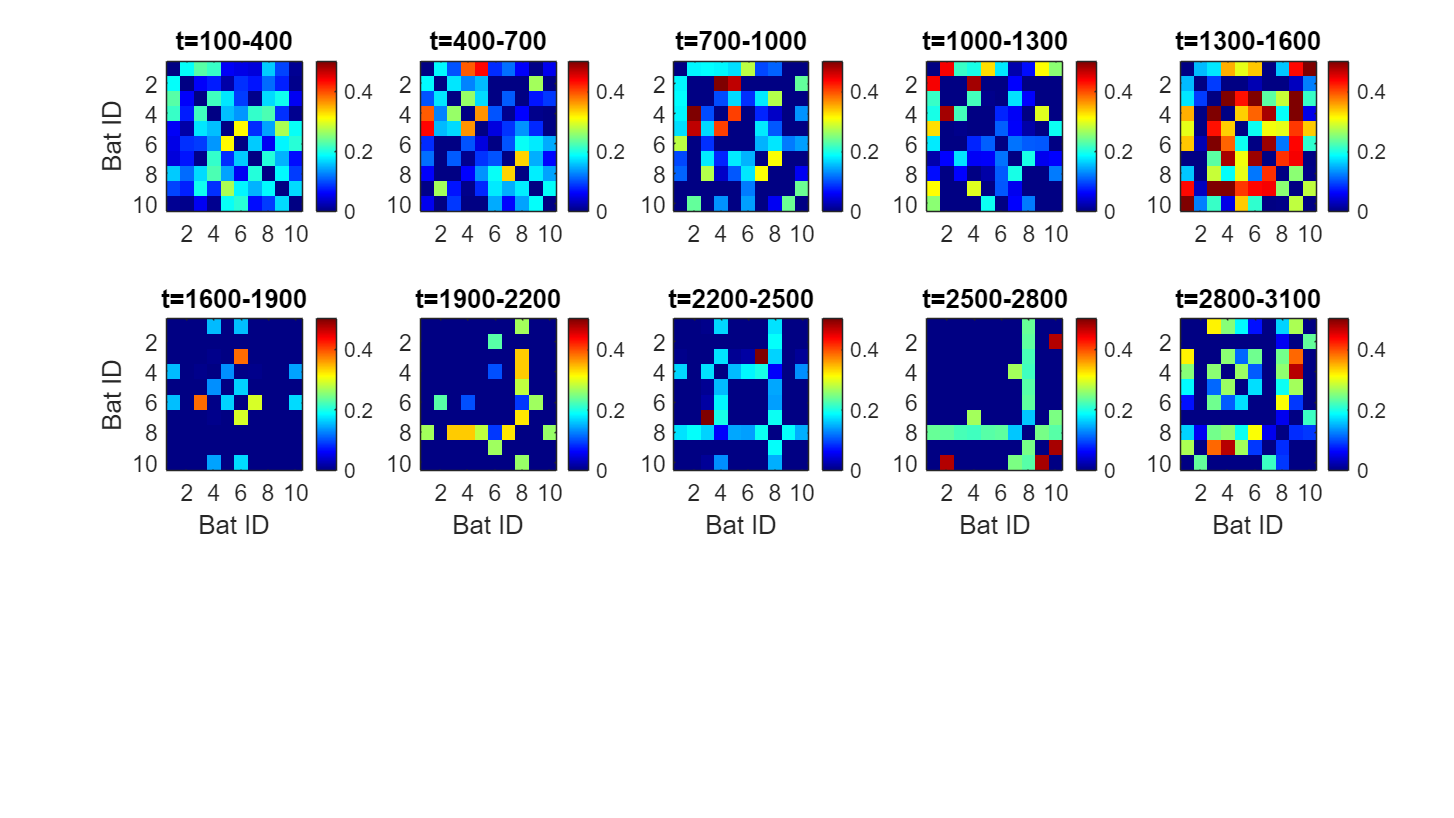

t_edges = 100:300:t(end); % every 5 mins
adj_corr = zeros(length(t_edges)-1,1);
figure
set(gcf,'units','normalized','Position',[0 0 1 1])
tiledlayout(3,5,'TileSpacing','tight')
for i = 1:length(t_edges)-1
    [adj_trace, ~, ~] = compute_adjacency(BhvData,'t_range',t_edges(i:i+1));
    adj_mat = cellfun(@mean, adj_trace);
    adj_mat(isnan(adj_mat)) = 0;

    if i>1
        adj_corr(i-1) = corr2(adj_mat,pre_adj_mat);
    end
    pre_adj_mat = adj_mat;

    if i <= 10
        nexttile
        imagesc(adj_mat)
        colorbar
        colormap jet
        clim([0 0.5])
        title(sprintf('t=%d-%d',t_edges(i),t_edges(i+1)))
        if mod(i,5) == 1
            ylabel('Bat ID')
        end
        if i > 5
            xlabel('Bat ID')
        end
        set(gca,'FontSize',14)
    end
end

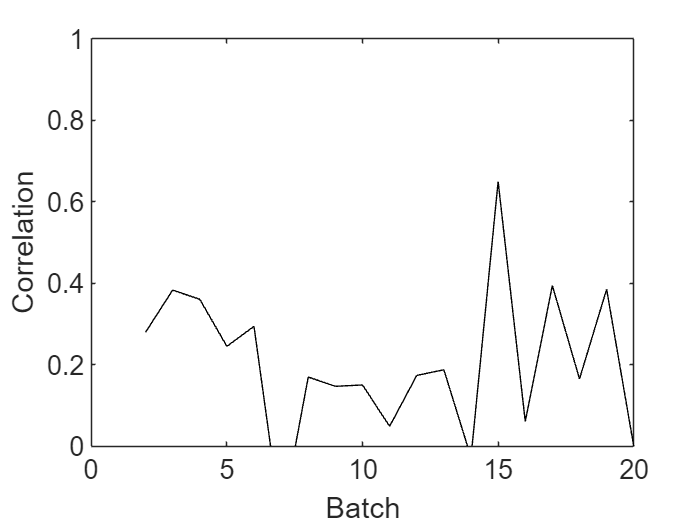


% Correlation
figure
plot(2:length(t_edges),adj_corr,'k')

xlabel('Batch')
ylabel('Correlation')
set(gca,'FontSize',16)
ylim([0 1])

### Spatial sparcity

spartcity can be represented by the number of elements above the threashold in adjancency matrix.

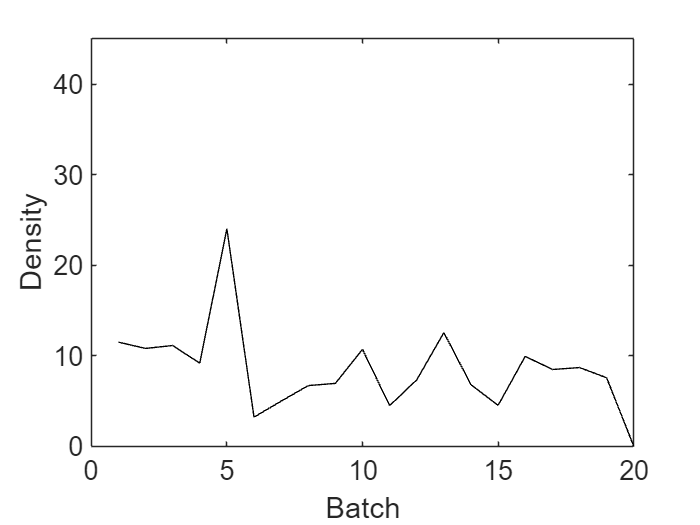

t_edges = 100:300:t(end); % every 5 mins
adj_sparse = zeros(length(t_edges),1); % sparsity
th = 0.2; % threshold
% figure
% set(gcf,'units','normalized','Position',[0 0 1 1])
% tiledlayout(3,5,'TileSpacing','tight')
for i = 1:length(t_edges)-1
    [adj_trace, ~, ~] = compute_adjacency(BhvData,t_edges(i:i+1));
    adj_mat = cellfun(@mean, adj_trace);
    adj_mat(isnan(adj_mat)) = 0;

    % adj_sparse(i) = nnz(adj_mat > th)/2;
    adj_sparse(i) = sum(adj_mat(:));
end

figure
plot(adj_sparse,'k')
xlabel('Batch')
ylabel('Density')
ylim([0 45])
set(gca,'FontSize',16)

% # frequency of feeder landings
is_fd_land = [];
t_land = [];
for bb = 1:n_bats
    is_fd_land = [is_fd_land; Flights(bb).is_fd_land];
    t_land = [t_land; Flights(bb).t_land_sec(:,1)];
end

t_fd_land = 
% clim([0 1])